# Nonlinear Validation of the System and Measurements

First, bringing in the provided simulated data, and the simulation parameters as described in `OrbitDetermination-fall2023.pdf.`

% simulation parameters
load sim_setup.mat
% bringing in simulation data
load orbitdetermination-finalproj_data_2023_11_14.mat 

Please note that any variables specified in the table from the assignment are loaded in `sim_setup.m`.

Many functions were written to assist this project. All of them live below. 

addpath('./functions/')

## Nonlinear State Simulation

Looking at the state evolution with initial conditions as described in the assignment, using `ode45():`

x_0 = [r_nom; dr_nom];                  % Initial conditions
n = length(x_0');                       % number of state variables
t_obs_meas = unique(y_table(:, 1));     % Times of interest, where there are observations 
t_obs = t_0:dt_obs:t_f;                 % Times of interest, where there are observations 
steps_obs = length(t_obs);      
steps_obs_meas = length(t_obs_meas);

% Solving the ODE with ICs and times of interest
options = odeset('RelTol',1e-12);
[~,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_obs, x_0, options);


### Plotting non-linear simulation solution

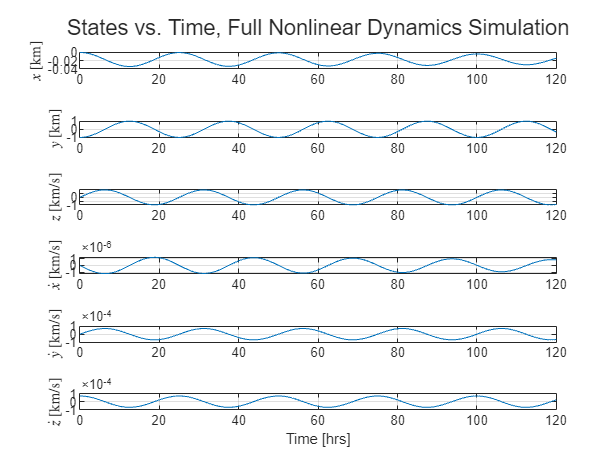

figure;
fig = tiledlayout(n,1);
ylabels = ["$x$ [km]", "$y$ [km]","$z$ [km/s]","$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    plot(t_obs/60/60,x_ode45(:,i))
    xlim([t_obs(1)/60/60, t_obs(end)/60/60])
    ylabel(ylabels(i),Interpreter='latex')
    grid on
end
xlabel("Time [hrs]")
title(fig,"States vs. Time, Full Nonlinear Dynamics Simulation")

### Plotting SC in asteroid-centered, asteroid-intertial frame

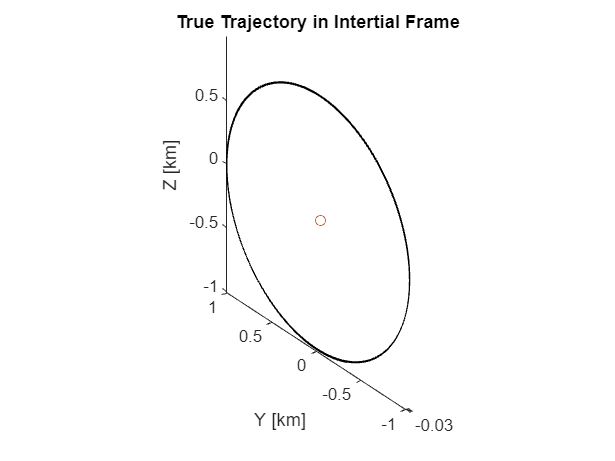

figure;
plot3(x_ode45(:,1),x_ode45(:,2),x_ode45(:,3),'black',0,0,0,'o')
axis equal
title("True Trajectory in Intertial Frame")
ylabel("Y [km]")
zlabel("Z [km]")

### Plotting SC in asteroid-centered, asteroid-rotating frame

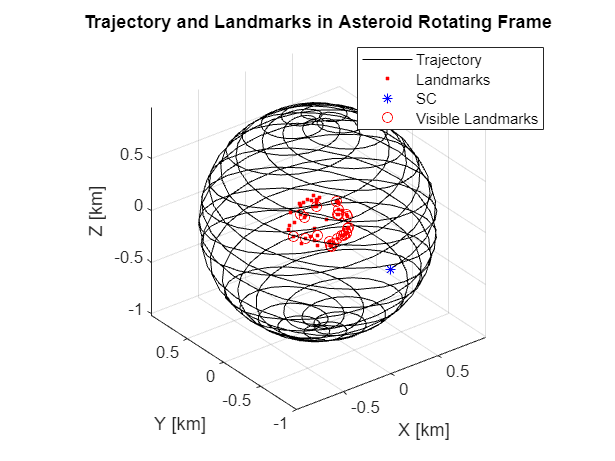

% Translating coordinate frames
r = zeros(steps_obs,3);
for i = 1:steps_obs
    t = t_obs(i);
    R_NA = R_NA_t(t);           % creates rotation matrix based on rotation of asteroid
    r(i,:) = R_NA * x_ode45(i,1:3)';
end

figure;
meas_idx = 1;                                               % time index of interest
meas_idx_y_table = find(y_table(:,1) == t_obs(meas_idx));   % y table indices showing visible landmakrs
vis_sats = y_table(meas_idx_y_table,2);                     % satellites visible at this time
plot3(r(:,1),r(:,2),r(:,3),'black',pos_lmks_A(1,:),pos_lmks_A(2,:),pos_lmks_A(3,:),'r.', ...
    r(meas_idx,1),r(meas_idx,2),r(meas_idx,3),'b*', ...
    pos_lmks_A(1,vis_sats),pos_lmks_A(2,vis_sats),pos_lmks_A(3,vis_sats),'ro')
axis equal
xlabel("X [km]")
zlabel("Z [km]")
ylabel("Y [km]")
grid on
legend('Trajectory','Landmarks','SC','Visible Landmarks','Location','northeast')
title("Trajectory and Landmarks in Asteroid Rotating Frame")

## Measurement Simulations

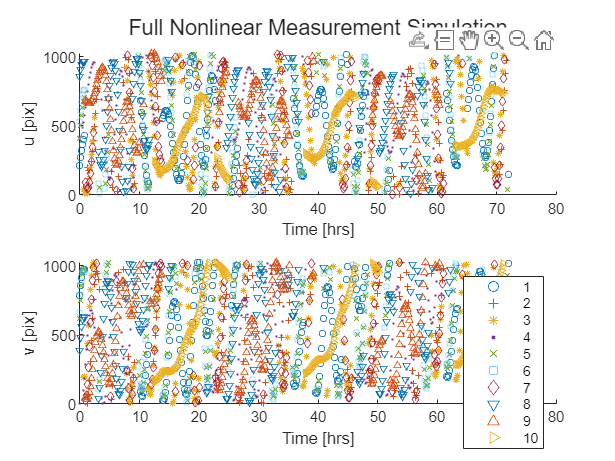

p = 2;                                          % number of measurement variables
num_marks = length(pos_lmks_A);
y_truth = ones(p*num_marks,steps_obs_meas)*NaN;      % 3D array of measurments at each OBSERVATION step.
    % NOTE: indexing order is strange to not have to flatten results.
    % Initialized to NaN to make sure no bad zero values make it through. 

% retrieving truth measurments for each measurement step
for meas_idx = 1:steps_obs_meas
    t_meas = t_obs_meas(meas_idx);               % Time of measurement
    x_nom_k = x_ode45(meas_idx,:)';                    % Truth state at this time

    % Making truth observations at observation times
    RNC = R_CtoN(:,:,meas_idx);                 % instrument coordinate system at this time

    % checking measurments for every landmark at this time
    for ii = 1:num_marks
        rows = (p*(ii-1)+1):(p*ii);             % Rows corresponding to this landmark in the measurement matrix
        lp = pos_lmks_A(:,ii);                         % landmark location
        % making the measurement at this time, this satellite location, for this landmark.
        y_truth(rows,meas_idx) = y_measured(lp,x_nom_k,RNC,t_meas,false,true);  
    end
end

% plotting observations
figure
fig = tiledlayout(2,1);
mkrs = ["o","+","*",".","x","square","diamond","v","^",">"];
plt_mks = length(mkrs);
sz = 15;    

% plotting u data
nexttile(fig)
hold on 
for i = 1:10
    s = scatter(t_obs_meas/60/60,y_truth(i*p-1,:),mkrs(i));
    s.SizeData = sz;
end
hold off
xlabel('Time [hrs]')
ylabel('u [pix]')

% plotting v data
nexttile(fig)
hold on 
for i = 1:10
    s = scatter(t_obs_meas/60/60,y_truth(i*p,:),mkrs(i));
    s.SizeData = sz;
end
hold off

% formatting
xlabel('Time [hrs]')
ylabel('v [pix]')
legend(string(1:10))
title(fig,"Full Nonlinear Measurement Simulation")

## DT LTI State Simulation, No Noise

% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);

% Static input
u = a_SRP;

% CT Gamma matrix
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W = zeros(m);             % CT process noise matrix

x_pert = [1e-5,1e-5,1e-5,1e-7,1e-7,1e-7]';                  % initial pertibation

% Initializing matrices
dx_DT = zeros(steps_obs_meas,n); 
x_DT = zeros(steps_obs_meas,n);
y_DT = ones(num_marks*p,steps_obs_meas)*NaN;
dx_DT(1,:)= x_pert';                                        % initializing pertibation
x_DT(1,:) = x_ode45(1,:) + dx_DT(1,:);                      % initial state + pertibation
for kp1 = 2:steps_obs_meas
    % calculating nominal state
    x_nom_k = x_ode45(kp1-1,:)';
    x_nom_k_plus = x_ode45(kp1,:);
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt_obs,A,B,Gamma,W);

    % deviation at the next time step
    dx_DT(kp1,:) = F*dx_DT(kp1-1,:)';

    % next state
    x_DT(kp1,:) = x_ode45(kp1,:) + dx_DT(kp1,:);

    % --- MEASUREMENT STEP --- %
    RNC = R_CtoN(:, :, kp1);                       % ADCS instrument axes at this step

    % perfoming H matrix calculations
    for i = 1:num_marks
        % Getting the visible landmark of interest
        lp = pos_lmks_A(:,i);                         % landmark coordinates in asteroid-fixed frame

        % obtaining H matrix for this landmark at next time step
        H_i = H_k(lp,x_nom_k_plus',t_obs_meas(kp1),RNC);

        % storing these values
        rows = (p*(i-1)+1):(p*i);                       % Rows corresponding to this landmark
        if ~anynan(y_truth(rows,kp1))
            y_DT(rows,kp1) = H_i * dx_DT(kp1,:)';
        end
    end
end

Plotting the predicted deviations

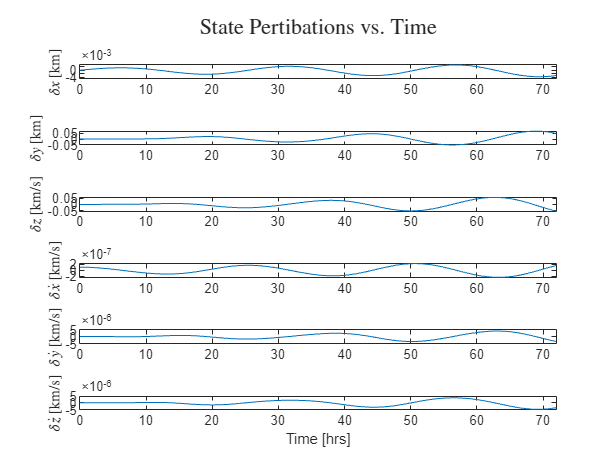

figure;
fig = tiledlayout(n,1);
ylabels =   ["$ \delta x$ [km]", "$\delta  y$ [km]","$\delta z$ [km/s]", ...
            "$\delta \dot x$ [km/s]", "$\delta \dot y$ [km/s]","$\delta \dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    plot(t_obs_meas/60/60,dx_DT(:,i))
    xlim([0, 72])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"State Pertibations vs. Time", Interpreter='latex')

## DT LTI Measurement Simulation, No Noise

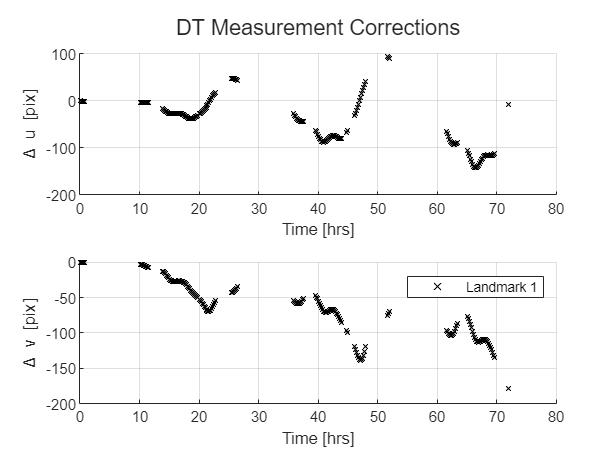

% linearized measurement simulations 
% plotting observations
figure
fig = tiledlayout(2,1);
mkrs = "x";
plt_mks = 1;
sz = 15;    

% plotting u data
nexttile(fig)
hold on 
s = scatter(t_obs_meas/60/60,y_DT(plt_mks*p-1,:),mkrs,'black');
s.SizeData = sz;
hold off
grid on
xlabel('Time [hrs]')
ylabel('\Delta u [pix]')
xlim([0,80])

% plotting v data
nexttile(fig)
hold on 
s = scatter(t_obs_meas/60/60,y_DT(plt_mks*p,:),mkrs,'black');
s.SizeData = sz;
hold off
grid on 
xlabel('Time [hrs]')
ylabel('\Delta v [pix]')
xlim([0,80])

legend('Landmark 1')
title(fig,"DT Measurement Corrections")